clear all

[pathsSpikes tmp] = ReadPCAPaths('D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\spikes');

[HIP] = ReadUnitTable("A2",6,'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Unit_Table_HIP_Simplified_Marzo_2024.xlsx');
% Change the sheet number depeding on what you want to plot
[pathsSpikesPCA] = pathsPCA(tmp,pathsSpikes,HIP);

[BST, SPK, SPK9] = ExtractMatFiles(HIP,pathsSpikesPCA);

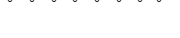


for i = 1:size(HIP,1)
[NormalizedIndexes histcenters histdatstd1 histdatstd2 histdatdev1 histdatdev2 histdatctr1ca histdatctr2ca histdatctr1cd histdatctr2cd] = IndexGeneratorDensity(SPK(i).spikedata,HIP(i,7).x1,HIP(i,8).x2);
NormalizedIndexesTable(i,:) = NormalizedIndexes;
STD_F1_F2(i,:) = (histdatstd1 + histdatstd2)./2;
DEV_F1_F2(i,:) = (histdatdev1 + histdatdev2)./2;
CTR_F1_F2(i,:) = (histdatctr1ca + histdatctr2ca + histdatctr1cd + histdatctr2cd)./4;

N(i,:) = sqrt( (mean(DEV_F1_F2(i,:)))^2 + (mean(STD_F1_F2(i,:)))^2 + (mean(CTR_F1_F2(i,:)))^2);

STD_F1_F2(i,:) = STD_F1_F2(i,:)/N(i,:);
DEV_F1_F2(i,:) = DEV_F1_F2(i,:)/N(i,:);
CTR_F1_F2(i,:) = CTR_F1_F2(i,:)/N(i,:);

% histdatstd1Table(i,:) = histdatstd1/max(histdatstd1);
% histdatstd2Table(i,:) = histdatstd2/max(histdatstd2);
% histdatdev1Table(i,:) = histdatdev1/max(histdatdev1);
% histdatdev2Table(i,:) = histdatdev2/max(histdatdev2);
% histdatctr1caTable(i,:) = histdatctr1ca/max(histdatctr1ca);
% histdatctr2caTable(i,:) = histdatctr2ca/max(histdatctr2ca);
% histdatctr1cdTable(i,:) = histdatctr1cd/max(histdatctr1cd);
% histdatctr2cdTable(i,:) = histdatctr2cd/max(histdatctr2cd);
end

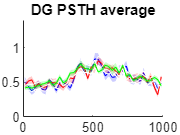


MeanSTD = mean(STD_F1_F2);
MeanDEV = mean(DEV_F1_F2);
MeanCTR = mean(CTR_F1_F2);

SEM_STD = std(STD_F1_F2)./sqrt(length(STD_F1_F2));
SEM_DEV = std(DEV_F1_F2)./sqrt(length(DEV_F1_F2));
SEM_CTR = std(CTR_F1_F2)./sqrt(length(CTR_F1_F2));

figure
% plot(histcenters, MeanSTD)
% hold on
shadedErrorBar(histcenters, MeanSTD,SEM_STD,'lineProps','b')
hold on
shadedErrorBar(histcenters, MeanDEV,SEM_DEV,'lineProps','r')
shadedErrorBar(histcenters, MeanCTR,SEM_CTR,'lineProps','g')
ylim([0 1.4])
title('DG PSTH average')

% cd 'D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\HIPDATA\Indexes\CA1';
% save('NormalizedIndexesTable.mat', 'NormalizedIndexesTable');

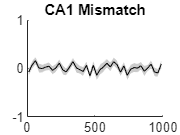

MMN = MeanDEV - MeanSTD;
for i = 1:size(SEM_STD,2)
SEM_MMN(1,i) = sqrt( (SEM_STD(1,i))^2 + (SEM_DEV(1,i))^2);
end
figure
shadedErrorBar(histcenters, MMN,SEM_MMN,'lineProps','k')
ylim([-1 1])
title('CA1 Mismatch')

PSTH_CA1.STD = STD_F1_F2; 
PSTH_CA1.DEV = DEV_F1_F2; 
PSTH_CA1.CTR = CTR_F1_F2;
save('D:\PRJ_HIPPOCAMPUS_JSS\PCASorting\Spike Matrix\PSTH_CA1_Aud.mat', 'PSTH_CA1');